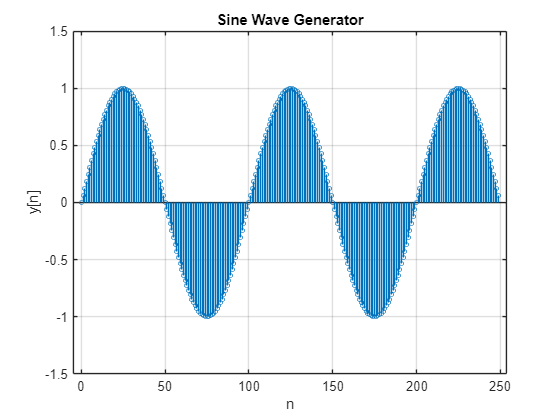

clc;
clear;
f  = 10e4;      
fs = 10e6;       
B  = 2*pi*f/fs;
    
alpha = 2*cos(B);
beta  = -1;
y(1) = 0;         % y[0]
y(2) = sin(B);    % y[1]

N  = 250;  
for i = 3:N
    y(i) = alpha*y(i-1) + beta*y(i-2);
end

figure(1);
n  = 0:N-1;  
stem(n, y, 'LineWidth', 0.5, 'MarkerSize', 3);  
xlabel('n'); 
ylabel('y[n]');
title('Sine Wave Generator'); 
grid on;